# ENME462 Studio 4 Time Response

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

The objective of this studio is to reinforce recetly learnt concepts of time response in the class.

## 1. First order system $G(s)=\frac{C(s)}{U(s)}=\frac{a}{s+a}=\frac{1}{\tau s+1}$

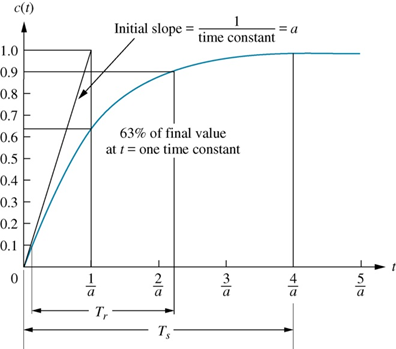

The specifications are defined for the **unit step input**.


$$C(s)=\frac{a}{s+a}\cdot\frac{1}{s}=\frac{1}{s}-\frac{1}{s+a}$$



$$c(t)=\mathcal{L}^{-1}\left(C(s)\right)=1-e^{-at}=1-e^{-t/\tau}$$


**Time constant** 


$$\tau=\frac{1}{a}$$


Initial slope


$$c\prime(t)=a\cdot e^{-at} \qquad c\prime(0)=a
$$


**Rise time:** time for the reponse to go from 0.1 to 0.9 of the steady state value.


$$c(2.31/a)=1-e^{-2.31}=0.9007 \\
c(0.11/a)=1-e^{-0.11}=0.1042\\
T_r=\frac{2.31}{a}-\frac{0.11}{a}=\frac{2.2}{a}$$


**Settling time:** time for the response to reach and stay within 2% of its final value.


$$c(4/a)=1-e^{-4}=0.9933 \\
T_s = 4/a$$


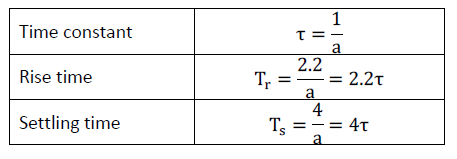

## 2. Second order system $G(s)=\frac{C(s)}{U(s)}=\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$  

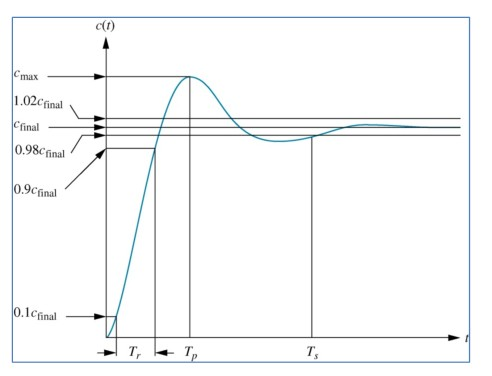

step response(under-damped)


$$C(s)=\frac{1}{s}\cdot\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}\\
=\frac{1}{s}-\frac{s+2\zeta \omega_{n}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}\\
=\frac{1}{s}-\frac{s+\zeta\omega_n}{(s+\zeta\omega_n)^{2}+(1-\zeta^2)\omega_n^2}-\frac{\zeta}{\sqrt{1-\zeta^2}}\cdot\frac{\sqrt{1-\zeta^2}\omega_n}{(s+\zeta\omega_n)^{2}+(1-\zeta^2)\omega_n^2} $$
 


$$\mathcal{L}[e^{-at}f(t)]=F(s+a) \qquad
\mathcal{L}[\cos(\omega t)]=\frac{s}{s^2+\omega^2} \qquad
\mathcal{L}[\sin(\omega t)]=\frac{\omega}{s^2+\omega^2} \qquad
\omega_d=\sqrt{1-\zeta^2}\omega_n$$



$$c(t)=\mathcal{L}^{-1}(C(s))=1-e^{-\zeta\omega_nt}\left(\cos(\omega_dt)+\frac{\zeta}{\sqrt{1-\zeta^2}}\sin(\omega_dt)\right)$$


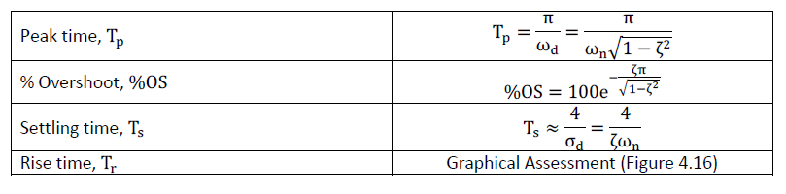

## 3. Antenna Control System:

What is the natural frequency, damping ratio, percentage of overshoot, and settling time for the open-loop response. Using a step response in MATLAB as computed in Studio1, these values will be verified.

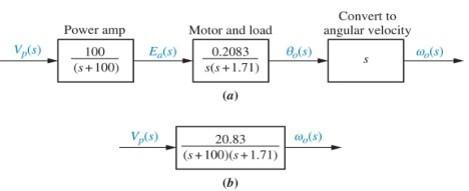

Transfer function:


$$G=\frac{20.83}{(s+100)(s+1.71)}=\frac{20.83}{s^2+101.7s+171}$$


For second order systems:


$$\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$$


Natural frequency: $\omega_n=\sqrt{171}=13.08$

Damping ratio: $\zeta=\frac{2\zeta\omega_n}{2\omega_n}=\frac{101.7}{2\cdot13.08}=3.89$ (Over damped)

step response :


$$\omega_o(s)=\frac{1}{s}\cdot\frac{20.83}{(s+100)(s+1.71)}=\frac{0.122}{s}+\frac{2.12\cdot10^{-3}}{s+100}-\frac{0.124}{s+1.71}
$$



$$\omega_o(t)=0.122+(2.12\cdot10^{-3})e^{-100t}-0.124e^{-1.71t}$$


consider as first order system with time constant $\tau=\frac{1}{a}=\frac{1}{1.71}=0.585$

rise time : $T_r = 2.2\cdot\frac{1}{a}=1.28$

setting time: $T_s=4\cdot\frac{1}{a}=2.34$

%% 1) PFE
num = 20.83;
den = poly([0, -100, -1.71]);
[r,p,k] = residue(num,den);

syms s
Ws = r(1)/(s - p(1)) + r(2)/(s - p(2)) + r(3)/(s - p(3));
Ws = vpa(Ws,3)

$$Ws = \frac{0.00212}{s+100.0}-\frac{0.124}{s+1.71}+\frac{0.122}{s}$$

Wt = ilaplace(Ws);
Wt = vpa(Wt,3)

$$Wt = 0.00212\,{\mathrm{e}}^{-100.0\,t}-0.124\,{\mathrm{e}}^{-1.71\,t}+0.122$$

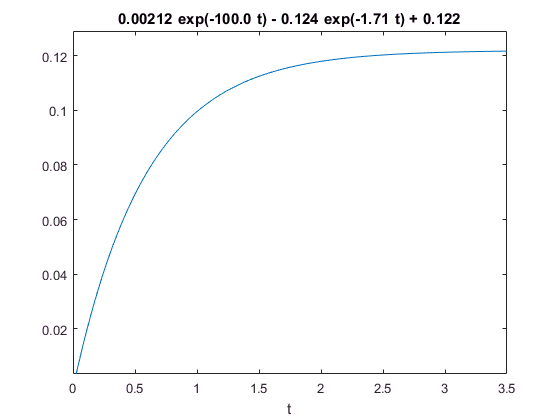

ezplot(Wt,[0, 3.5])

%% 2) Control toolbox
s = zpk('s'); 
G = 20.93 / ((s+100)*(s+1.71))    


G =
 
       20.93
  ----------------
  (s+100) (s+1.71)
 
Continuous-time zero/pole/gain model.



damp(G)      % poles, damping ratio, wn

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.71e+00     1.00e+00       1.71e+00         5.85e-01    
 -1.00e+02     1.00e+00       1.00e+02         1.00e-02    


stepinfo(G)  % step response information

ans =         RiseTime: 1.2850
    SettlingTime: 2.2980
     SettlingMin: 0.1105
     SettlingMax: 0.1223
       Overshoot: 0
      Undershoot: 0
            Peak: 0.1223
        PeakTime: 4.2820


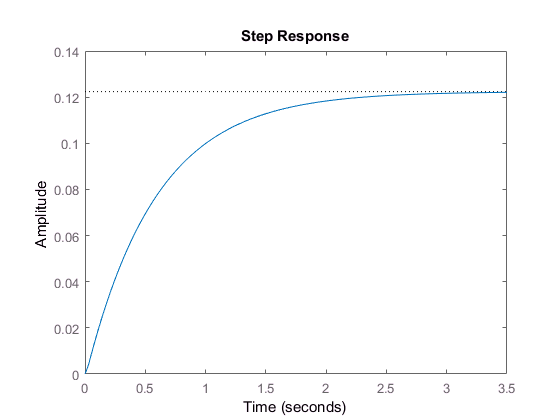

step(G)      % step resonpse plot 

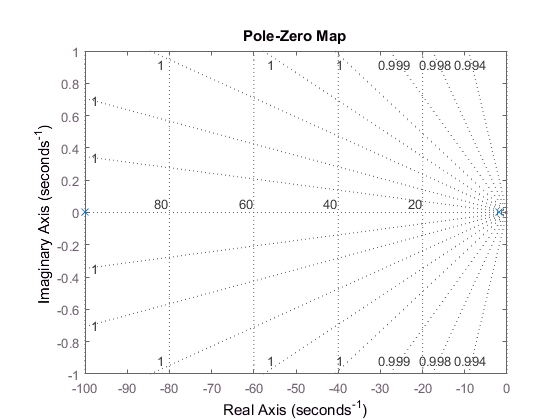

pzmap(G)     % poles zeros map 
grid on

## 4. Unmanned Free-Swimming Submersible Vehicle - Open Loop Pitch presonse:

An UFSS and its corresponding pitch control system is shown in the figure below. the time response of the vehicle dyanmics that relates the pitch angle output to the elevator deflection input is studied now. 

a) Discuss the time response specifications using only second order poles.

b) Compute the pitch time response using both hand calculations and MATLAB.

c) Analyze the effect of the additional pole and zero in the system and judge whether the second order response can be appoximated for the system.

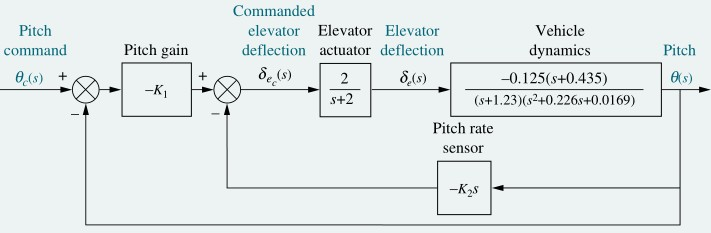

**a) Second order poles only,**

standard 2nd order system: $\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$


$$s^2+0.226s+0.0169\\
\omega_n^2=0.0169 \qquad 2\zeta\omega_n=0.226\\
\omega_n=0.13 \qquad \zeta=0.869 \qquad \omega_d=\sqrt{1-\zeta^2}\omega_n=0.0643$$


Pole location $-\zeta\omega_n \pm j\omega_n\sqrt{1-\zeta^2}\rightarrow -0.113 \pm 0.0643j$

%Overshoot: $100\cdot e^{-\frac{\zeta\pi}{\sqrt{1-\zeta^2}}}=0.399\% \qquad T_p=\frac{\pi}{\omega_d}=48.9 \qquad T_s=\frac{4}{\zeta\omega_n}=35.4$

%% 1) Hand calculation
omega_n = sqrt(0.0169)

omega_n = 0.1300

zeta = 0.226/(2* omega_n)

zeta = 0.8692

omega_d = sqrt(1 - zeta^2) * omega_n

omega_d = 0.0643

OS = exp(-zeta*pi/sqrt(1-zeta^2)) *100

OS = 0.3993

Tp = pi / omega_d

Tp = 48.8790

Ts = 4 / (zeta*omega_n)

Ts = 35.3982

%% 2) Control toolbox
s = zpk('s');
G = 0.0169 / (s^2 + 0.226*s + 0.0169);
damp(G) 

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.13e-01 + 6.43e-02i     8.69e-01       1.30e-01         8.85e+00    
 -1.13e-01 - 6.43e-02i     8.69e-01       1.30e-01         8.85e+00    


stepinfo(G)

ans =         RiseTime: 21.1397
    SettlingTime: 33.6748
     SettlingMin: 0.9020
     SettlingMax: 1.0040
       Overshoot: 0.3993
      Undershoot: 0
            Peak: 1.0040
        PeakTime: 48.9045


**b) Time response,**


$$\theta(s)=\frac{1}{s}\cdot\frac{0.125(s+0.435)}{(s+1.23)(s^2+0.226s+0.0169)}\\
\theta(s)=2.62\frac{1}{s}+0.0645\frac{1}{s+1.23}-\frac{2.68[(s+0.113)+1.3\sqrt{0.00413}]}{(s+0.113)^2+0.00413}$$



$$\theta(t)=2.62+0.0645e^{-1.23t}-2.68e^{-0.113t}(\cos(0.0643t)+1.3\sin(0.0643t))$$


%% 1) Inverse Lapalce transformation
syms s % Construct symbolic object for Laplace variable 's'.
num = 0.125 * (s+0.435);
den = s * (s+1.23) * (s^2 + 0.226*s + 0.0169);
theta = ilaplace(num/den); 
theta = vpa(theta,3) 

$$theta = 0.0645\,{\mathrm{e}}^{-1.23\,t}-2.68\,{\mathrm{e}}^{-0.113\,t}\,\left(\cos\left(0.0643\,t\right)+1.3\,\sin\left(0.0643\,t\right)\right)+2.62$$

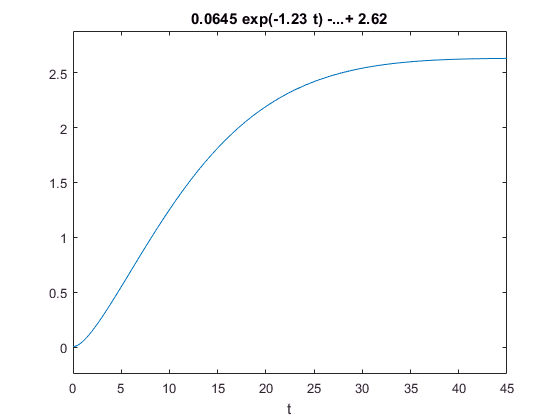

%% 2) Control Toolbox
s = zpk('s');
num = 0.125*(s+0.435);
den = (s+1.23)*(s^2+0.226*s+0.0169);
G = num/den;
ezplot(theta,[0,45])

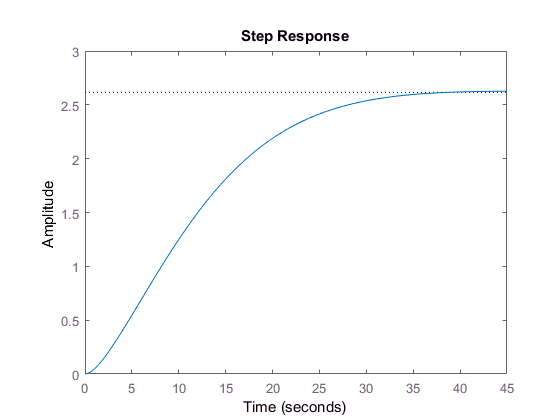

step(G)

**c) Effect of extra pole & zero on the transient response **

s= zpk('s'); % Construct symbolic object for Laplace variable 's'.
num = 0.125 * (s+0.435);
den = (s+1.23) * (s^2 + 0.226*s + 0.0169);
G = num / den;

num2 = sqrt(0.0169);
den2 = s^2 + 0.226*s + 0.0169;
G2 = num2 / den2;
stepinfo(G)

ans =         RiseTime: 20.3983
    SettlingTime: 31.7417
     SettlingMin: 2.3660
     SettlingMax: 2.6269
       Overshoot: 0.4233
      Undershoot: 0
            Peak: 2.6269
        PeakTime: 46.8668


stepinfo(G2)

ans =         RiseTime: 21.1397
    SettlingTime: 33.6748
     SettlingMin: 6.9387
     SettlingMax: 7.7230
       Overshoot: 0.3993
      Undershoot: 0
            Peak: 7.7230
        PeakTime: 48.9045


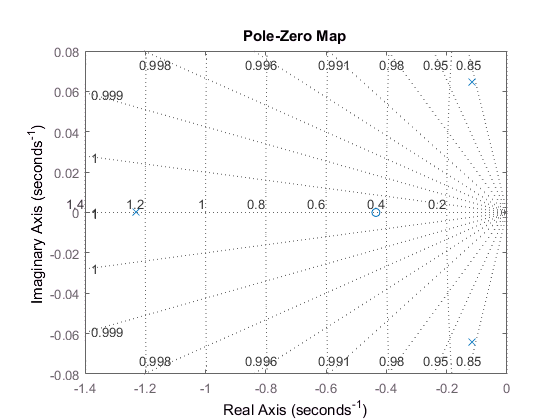

pzmap(G)
grid on

Fast poles : open left half plane systems poles which are much farther away from the stability boundary( imaginary axis) than other sytem poles.

Dominant or slow poles: poles which are closer to the stability boundary than the rest of the sytem poles.

Approximation rule: the real part of the dominant poles is **less than one tenth **of the third pole 